**SECTION 1: Load up data and remove courses to be excluded**

First load up all the data

clear all;
figure;
set(gcf, 'Position', [1 1 1200 800]);
set(gcf, 'PaperPositionMode', 'auto');
[CourseRegnData, CourseCodes, CourseCredits, StudentIds, StudentNames] = ReadCSVFilesAndFormDataTable_Dec2019('Jan2022_CoursePreRegData_FileList.ForAtharv.txt');

Statistics about Course Pre-Registration
Total number of students = 473
Total number of courses = 110
Number of students who have pre-registered = 367(77.5899%)
Median number of courses / student for students who have pre-registered = 6; range = 3 - 11
Median number of credits / student for students who have pre-registered = 23; range = 12 - 34
Median number of students / course = 14; range = 1 - 85


CourseNames = GetCourseNames('sem32_CourseList.csv', CourseCodes);

Finished


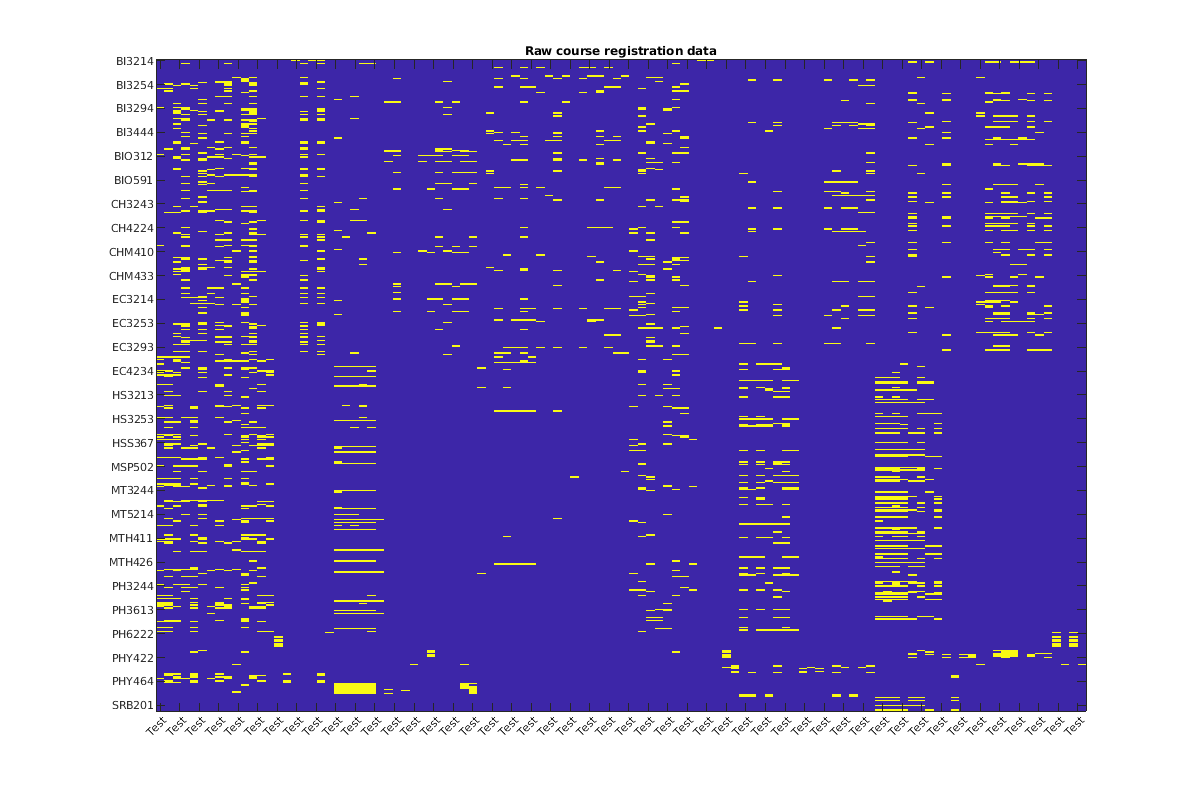


imagesc(1:1:length(StudentIds), 1:1:length(CourseCodes), CourseRegnData);
set(gca, 'XTick', 1:10:length(StudentIds), 'XTickLabel', StudentNames(1:10:end), 'FontSize', 8);
set(gca, 'YTick', 1:4:length(CourseCodes), 'YTickLabel', CourseCodes(1:4:end), 'FontSize', 8);
title('Raw course registration data');

Now set up courses to exclude

CoursesToExclude = {'BI3613' 'BI5223' 'BI6472' 'BIO402' 'CH1213' 'CH1223' 'CH3243' 'CH3253' 'CH3613' 'CH5212' 'CH6432' 'CH6442' 'CHM402' 'DS3613' 'DS4613' 'EC3613' 'ECS402' 'HS3613' 'HS6264' 'HSS402' 'LRP201' 'MSP502' 'MT3613' 'MT5614' 'MT6264' 'MT6274' 'MT6284' 'MT6294' 'MT6414' 'MTH402' 'PH3244' 'PH3613' 'PH5613' 'PH6212' 'PH6222' 'PHY402' 'PHY434' 'PRB201' 'PRC201' 'SRB201' 'SRC202'};
CoursesToCombine = [];

Now make new course registration data table with excluded courses

[CourseRegnData, CourseCodes, CourseCredits] = ExcludeCombineCourses(CourseRegnData, CoursesToExclude, CourseCodes, CourseCredits, CoursesToCombine);
DataTable = CourseRegnData;

CourseNames = GetCourseNames('sem32_CourseList.csv', CourseCodes);

Finished


disp('');
disp('List of courses that are being considered for grouping');

List of courses that are being considered for grouping


disp('');

for i = 1:length(CourseCodes),
    disp([num2str(i), ':', CourseCodes{i}, ': ', CourseNames{i}]);
end

1:BI3214: Animal Physiology I



figure;
set(gcf, 'Position', [1 1 1200 800]);
set(gcf, 'PaperPositionMode', 'auto');
imagesc(1:1:length(StudentIds), 1:1:length(CourseCodes), CourseRegnData);
set(gca, 'XTick', 1:10:length(StudentIds), 'XTickLabel', StudentNames(1:10:end), 'FontSize', 8);
set(gca, 'YTick', 1:4:length(CourseCodes), 'YTickLabel', CourseCodes(1:4:end), 'FontSize', 8);
title('Course registration data for courses included in grouping');
save('2022Jan.StudentIds.CourseCodes.StudentNames.DataTable.mat', 'CourseCodes', 'DataTable', 'StudentIds', 'StudentNames', 'CourseNames');

**SECTION 2: Run the actual overlap calcuation and grouping script**

Now run the actual overlap calculation script

CheckOverlap_HexaOverlap_RawOverlaps_Jan2020(CourseRegnData, CourseCodes, CourseCredits, StudentIds, 12, [], [], [], 1, 25);

Total number of valid courses = 80
2000>>4000>>6000>>8000>>10000>>
Median overlap score = 268: range = 152 - 404
Elapsed time is 5.669637 seconds.
Elapsed time is 294.503882 seconds.
=========== Run #1============
Added group #1 : Overlap Score = 0
Group #1: Overlap = 0
Group #2: Overlap = 0
Group #3: Overlap = 0
Group #4: Overlap = 0
Group #5: Overlap = 11
Group #6: Overlap = 24
Group #7: Overlap = 28
Group #8: Overlap = 11
Group #9: Overlap = 28
Group #10: Overlap = 20
Group #11: Overlap = 15
Group #12: Overlap = 35
Group #1: Overlap = 0
Group #2: Overlap = 0
Group #3: Overlap = 0
Group #4: Overlap = 19
Group #5: Overlap = 0
Group #6: Overlap = 24
Group #7: Overlap = 28
Group #8: Overlap = 11
Group #9: Overlap = 28
Group #10: Overlap = 20
Group #11: Overlap = 15
Group #12: Overlap = 35
Group #1: Overlap = 0
Group #2: Overlap = 0
Group #3: Overlap = 0
Group #4: Overlap = 19
Group #5: Overlap = 20
Group #6: Overlap = 0
Group #7: Overlap = 28
Group #8: Overlap = 11
Group #9: Overlap = 2